# USE THE CAMERA OF WINDOWS

Construct a video input object.

obj= videoinput('winvideo')

Select the source to use for acquisition.

obj.SelectedSourceName = 'input1'


Summary of Video Input Object Using 'USB2.0 VGA UVC WebCam'.

   Acquisition Source(s):  input1 is available.

  Acquisition Parameters:  'input1' is the current selected source.
                           10 frames per trigger using the selected source.
                           'YUY2_160x120' video data to be logged upon START.
                           Grabbing first of every 1 frame(s).
                           Log data to 'memory' on trigger.

      Trigger Parameters:  1 'immediate' trigger(s) on START.

                  Status:  Waiting for START.
                           0 frames acquired since starting.
                           0 frames available for GETDATA.



View the properties for the selected video source object.

src_obj = getselectedsource(obj);
get(src_obj)

      General Settings:
        Parent = [1x1 videoinput]
        Selected = on
        SourceName = input1
        Tag = [0x0 string]
        Type = videosource

      Device Specific Properties:
        BacklightCompensation = on
        Brightness = 0
        Contrast = 50
        Exposure = -6
        ExposureMode = auto
        FrameRate = 30.0000
        Gain = 64
        Gamma = 300
        Hue = 0
        Pan = 0
        Roll = 0
        Saturation = 50
        Sharpness = 50
        Tilt = 0
        WhiteBalance = 4600
        WhiteBalanceMode = auto
        Zoom = 0



Preview a stream of image frames.

preview(obj)

Acquire and display a single image frame.

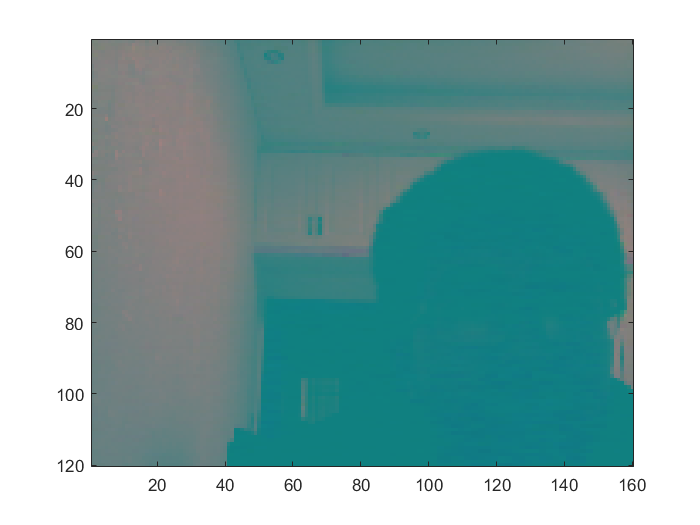

frame = getsnapshot(obj);
image(frame);

Remove video input object from memory.

delete(obj);